# Final Assignment 5SMB0

Kijk naar model validatie slides!! make een bode van parametric en non-parametric en vergelijk. zijn ze hetzelfde??? zo nee wat gaat er waar verkeerd. een dubbel check.

## Part 1: Understanding saturation and Butterworth filter

1.1 (3 points) The (partially) known parts of the system consist of F(q) and S. De termine by an initial experiment the parameter M and explain what influence F(q) and S will have on the identification of the unknown part H and G. This could be, e.g., on the remaining steps of the system identification cycle, limitations on the obtained final model, etc.

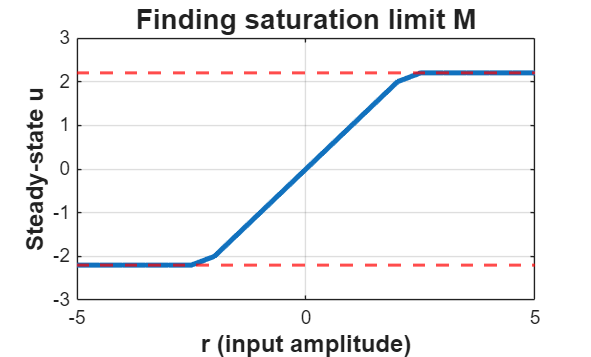

N = 500;
mode = 'open loop';

amplitudes = -5:0.5:5;
u_steady = zeros(size(amplitudes));

% loop over amplitudes and find steady state using the last 20 samples
for i = 1:length(amplitudes)
    r = amplitudes(i) * ones(N, 1);
    [u, f] = assignment_sys_14(r, mode);
    u_steady(i) = mean(u(end-20:end)); 
end
   
f = figure;

plot(amplitudes, u_steady, '-', 'LineWidth', 2.5);
hold on;

yline(2.2, '--r', 'LineWidth', 1.5);
yline(-2.2, '--r', 'LineWidth', 1.5);

xlabel('r (input amplitude)', 'FontSize', 12, 'FontWeight', 'bold'); 
ylabel('Steady-state u', 'FontSize', 12, 'FontWeight', 'bold');
title('Finding saturation limit M', 'FontSize', 14, 'FontWeight', 'bold');

grid on;



% Butterworth filter from assignment
b = [0.7157 1.4315 0.7157];
a = [1 1.3490 0.5140];

% Compute frequency response
[F, w] = freqz(b, a, 500);

% Magnitude in dB
mag_db = 20*log10(abs(F));

% Find -3dB cutoff 
cutoff_idx = find(mag_db <= -3, 1);
fc_hz = w(cutoff_idx)/(2*pi);     % Hz
fc_rad = w(cutoff_idx);           % rad/sample

fprintf('Cutoff: %.2f Hz (%.1f rad/s)\n', fc_hz, fc_rad);

Cutoff: 0.42 Hz (2.7 rad/s)


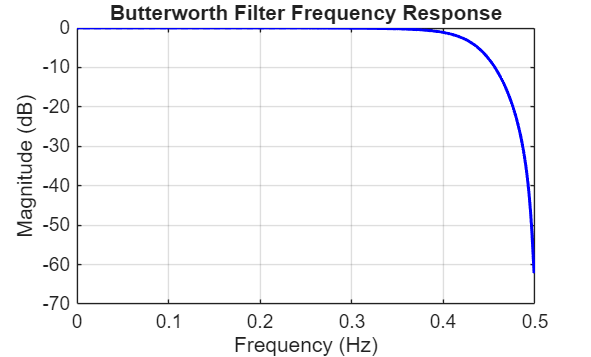


% Plot magnitude
figure; 
plot(w/(2*pi), 20*log10(abs(F)), 'b-', 'LineWidth', 1.5);
hold on; grid on;
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title('Butterworth Filter Frequency Response');

% legend('Filter response')

When looking at the graph we can duduce that the parameter M saturates at a steady state input above 2.2

## Part 2: Nonparametric identification

2.1 (4 points) We first want to get a rough idea of the frequency behavior of G0(q). To this end, we want to perform a preliminary experiment and apply nonparametric system identification using the collected data. The task is then to design an experiment of length N =1500. What type of reference shall be used? Give an expression of r(k) and motivate your choice.

Transient Detection

%%% Part 2: Non-parametric identification

N = 300;     % number of points per period
N_per = 5;   % number of excitation signal periods
P_skip = 1;  % number of excluded signal periods to exclude transients
fs = 1.0;    % sampling frequency in Hz
Ts = 1/fs;   % sampling interval in seconds
f0 = fs/N;   % frequency resolution in Hz

t = (0:1:N-1)*Ts; % time vector in sec 
f = (0:1:N-1)*f0; % frequency vector in Hz

%% 2.1: Nonparametric experiment design:  
% Multi-Sine Schroeder phase

% Dense Excitation over selected frequency range: 
fmin = 0.01;  %   lowest excited frequency in Hz
fmax = 0.48;  %  highest excited frequency in Hz
nmin = ceil(fmin/f0);  
nmax = floor(fmax/f0); 
bins = nmin:nmax;
w_bins = 2 * pi * f(bins+1); 

% Compute Butterworth Filter F(q) gain response
btt_num = [0.7157 1.4315 0.7157];
btt_den = [1 1.3490 0.5140];
F_butter = tf(btt_num, btt_den, 1.0);
F_gain = abs(squeeze(freqresp(F_butter, w_bins)));

% Construct the multi-sine schroeder phase signal
% Rescale amplitudes (Inverse Filter Gain) of Butterworth filter F(q),
% to keep excitation spectrum flat at input u
F = nmax-nmin+1;
A = zeros(1,N/2-1); 
A(bins+1) = 1.0 ./ F_gain; % Inverse filter gain scaling
phi = zeros(1,N/2-1); 
phi(bins+1) = -(bins-nmin+1).*(bins-nmin).*pi/F; % Schroeder phase
U = zeros(1,N);
U(bins+1) = A(bins+1).*exp(1i*phi(bins+1));

usp = real(ifft(U))*N; 
usp = 2.2*usp/std(usp); % Maximize signal power 
Usp = fft(usp);

% Check amplitude characteristics of reference signal
disp(['Maximum Amplitude of reference excitation: ' num2str(max(usp))])

Maximum Amplitude of reference excitation: 7.3292


Arlg = db(rms(abs(usp))); disp(['RMS Amplitude of reference excitation: ' num2str(Arlg) ' dB'])

RMS Amplitude of reference excitation: 6.834 dB


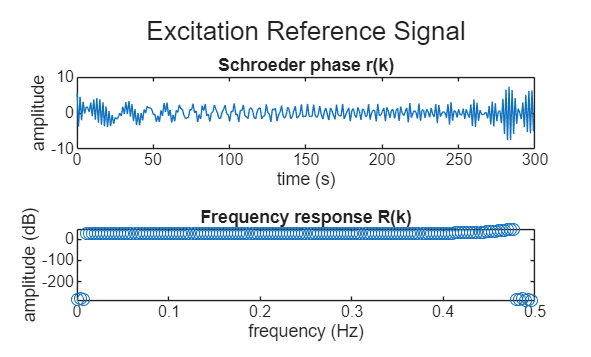


figure; tcl = tiledlayout(2,1); title(tcl,'Excitation Reference Signal')
nexttile; plot(t,usp); xlabel('time (s)'); ylabel('amplitude'); title('Schroeder phase r(k)');
nexttile; plot(f(1:end/2),db(Usp(1:end/2)),'o'); xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('Frequency response R(k)'); 

2.2 (4 points) Identify an FRF of the system. Motivate the chosen FRF estimator. What can we conclude from this FRF? Think of, e.g., high-frequency behavior, gain, res onance peaks, etc.

%% 2.2: Empirical Transfer Function Estimate
mode = 'open loop';
repeat_usp = repmat(usp, 1, N_per);
[u,y] = assignment_sys_14(repeat_usp,mode);
% Check if amplitude stays within operating range (excluding transient start)
disp(['Maximum Amplitude of input excitation, excluding 1st experiment: ' num2str(max(abs(u(N+1:end))))])

Maximum Amplitude of input excitation, excluding 1st experiment: 2.1565


Aulg = db(rms(abs(u(N+1:end)))); disp(['RMS Amplitude of input excitation, excluding 1st experiment: ' num2str(Aulg) ' dB'])

RMS Amplitude of input excitation, excluding 1st experiment: 1.6613 dB


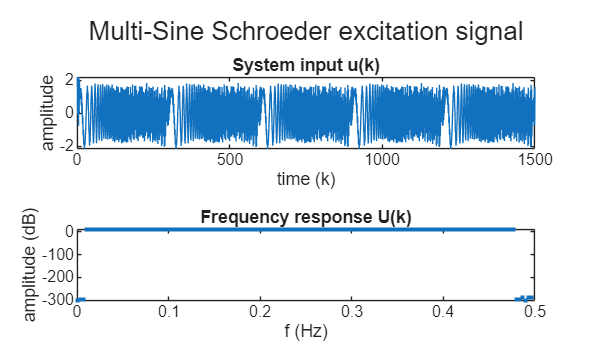


% Discard first period with transient system state
y_matrix = reshape(y, N, N_per);
u_matrix = reshape(u, N, N_per);
y_steady = y_matrix(:, P_skip+1:end);
u_steady = u_matrix(:, P_skip+1:end);
Y_steady = fft(y_steady);
U_steady = fft(u_steady);

% Average over steady experiments in time domain
u_avg = mean(u_steady, 2);
y_avg = mean(y_steady, 2);
U_avg = fft(u_avg);
Y_avg = fft(y_avg);

% Plot input characteristics of the system input
figure; tcl = tiledlayout(2,1); title(tcl,'Multi-Sine Schroeder excitation signal');
nexttile;plot(u(1:end)); xlabel('time (k)'); ylabel('amplitude'); title('System input u(k)'); 
nexttile;plot(f(1:end/2),db(U_avg(1:end/2)/N_per),'.'); xlabel('f (Hz)'); ylabel('amplitude (dB)'); title('Frequency response U(k)'); 

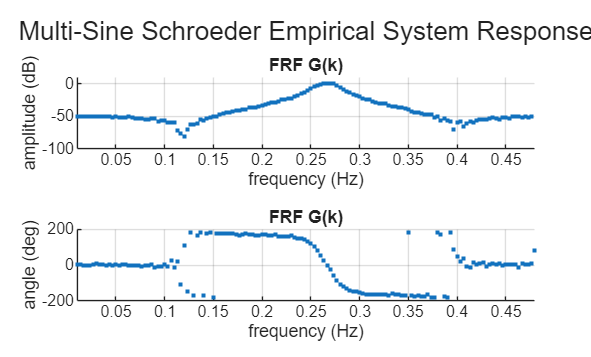


% Estimate the empirical transfer function
% Divide in the frequency domain the output Y over the input U to disregard filter dynamics
G = Y_avg ./ U_avg;

% Plot system characteristics of G
figure; tcl = tiledlayout(2,1); title(tcl,'Multi-Sine Schroeder Empirical System Response');
nexttile;hold on; grid on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('FRF G(k)'); xlim([fmin, fmax]); ylim([-100, 10]);
plot(f(1:end/2),db(G(1:end/2)),'.'); 
nexttile;hold on; grid on; xlabel('frequency (Hz)'); ylabel('angle (deg)'); title('FRF G(k)'); xlim([fmin, fmax]);
plot(f(1:end/2), angle(G(1:end/2)) * (180/pi),'.');

2.3 (4 points) Use the data generated in Part 2.1 to obtain an estimation of the non parametric noise model, i.e., derive an expression for estimating the noise spectrum Φv and plot the magnitude of the estimated noise power spectrum. What can you conclude from the estimated spectrum?

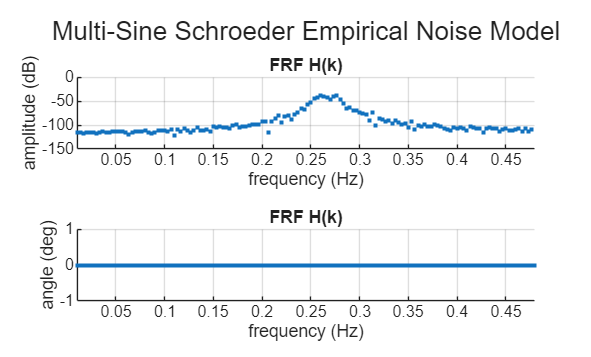

%% 2.3: Empirical Noise Model Estimate
% Variance between experiments,
% explains noise model H
F = var(Y_steady ./ U_steady, 0, 2);
% Plot noise characteristics of H
figure; tcl = tiledlayout(2,1); title(tcl,'Multi-Sine Schroeder Empirical Noise Model')
nexttile;hold on; grid on; xlabel('frequency (Hz)'); ylabel('amplitude (dB)'); title('FRF H(k)'); xlim([fmin, fmax]); ylim([-150, 0]);
plot(f(1:end/2),db(F(1:end/2)),'.'); 
nexttile;hold on; grid on; xlabel('frequency (Hz)'); ylabel('angle (deg)'); title('FRF H(k)'); xlim([fmin, fmax]);
plot(f(1:end/2), angle(F(1:end/2)) * (180/pi),'.');

If we compare the Bode plot (G) and the power specrtum (H), they bot look very similair in magnitude behaivior. Both have a resonance peak at 0.27 Hz. This suggest that th noise has similair/ the same poles as the system G.

### Dit is volgnens de slides module 3 slide 42?

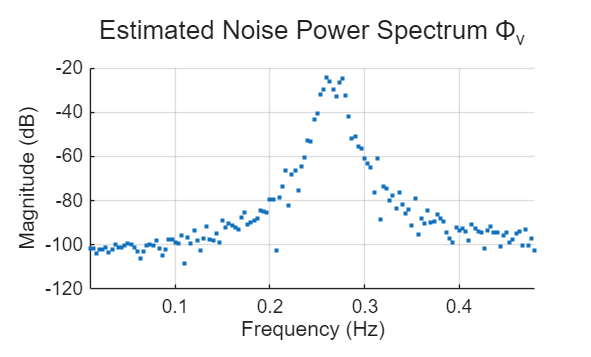

Y_mean = mean(Y_steady, 2);  % mean over periods, size (N,1)
Phi_v = (1/(N-1)) * sum(abs(Y_steady - Y_mean).^2, 2);  % slide 41 Lecture 3

% Plot noise power spectrum Phi_v
figure; tcl = tiledlayout(1,1); title(tcl,'Estimated Noise Power Spectrum \Phi_v')
nexttile; hold on; grid on;
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
xlim([fmin, fmax]);
plot(f(1:end/2), db(Phi_v(1:end/2)), '.');

## Part 3: Parametric identification and validation

3.1 (4 points) Based on the findings of the nonparametric identification, we want to get a parametric model of G0(q). Design a new experiment of length N = 3000. Choose a signal type of r(k) and motivate your choice.

The plots from part 2 suggest that th noise has similair/ the same poles as the system G. This means that we deal with an ARX/ ARMAX model structure (see lecture 6 slide 8).

% clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2; % niquist freq
Ts = 1/fs;  % sampling interval in seconds

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.01 0.45] / (fn);
[b_filt, a_filt] = butter(4, wn, 'bandpass');
r_filtered = filtfilt(b_filt, a_filt, r_white_noise);

% make the r signal and scale to stay within saturation limits
safe_amplitude = 2.2;             
r_scaled = r_filtered / max(abs(r_filtered));   
r = safe_amplitude * r_scaled;

r_max = max(abs(r))  

r_max = 2.2000


mode = 'open loop';
[u, y] = assignment_sys_14(r, mode);

u_max = max(abs(u))

u_max = 2.1857

3.2 (8 points) Using the designed input from Part 3.1, perform parametric identification of the system that yields a consistent estimate of G0. Motivate the choices that you make for, e.g., the model structure, model orders, validation methods, etc. Finally, compare the obtained results with the results from Part 2.

data = iddata(y, u, Ts);

% split data in train and test set
x_train = data(1:1500);
x_test = data(1501:3000);

delay = delayest(x_train)

delay = 4


% tune these maybe
na = 4; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 4; % nc is the order of the polynomial C(q)
nk = 0; % nk is the input-output delay

opt = armaxOptions;
opt.Focus = 'simulation';
opt.EnforceStability = true;

opt1 = arxOptions;
opt1.Focus = 'simulation';
opt1.EnforceStability = true;

% define systems
sys_arx = arx(x_train, [na, nb, nk], opt1)


sys_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                               
  A(z) = 1 + 0.3912 z^-1 + 1.842 z^-2 + 0.3542 z^-3 + 0.8213 z^-4                                 
                                                                                                  
  B(z) = 0.007124 + 0.001184 z^-1 - 0.002663 z^-2 + 0.001245 z^-3 + 0.007241 z^-4 + 3.062e-05 z^-5
                                                                                                  
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nk=0
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "x_train".
Fit to estimation data: 81.94% (simulation focus) 
FPE: 5.297e-06, MSE: 0.0007678                    
 


sys_armax = armax(x_train, [na, nb, nc, nk], opt)


sys_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                        
  A(z) = 1 + 0.4109 z^-1 + 1.839 z^-2 + 0.3712 z^-3 + 0.8143 z^-4                                
                                                                                                 
  B(z) = 0.004387 + 0.001506 z^-1 - 0.004711 z^-2 + 0.003302 z^-3 + 0.008319 z^-4 + 0.002738 z^-5
                                                                                                 
  C(z) = 1 + 0.2547 z^-1 + 0.1328 z^-2 - 0.1398 z^-3 - 0.216 z^-4                                
                                                                                                 
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nc=4   nk=0
   Number of free coefficients: 14
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using ARMAX on time domain da

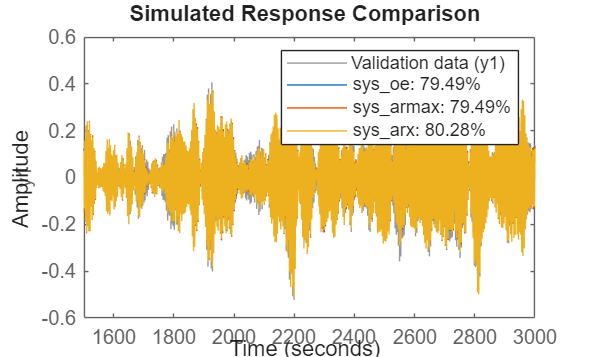

sys_oe = oe(x_train, [na, nb, nk]);

figure();
compare(x_test, sys_oe, sys_armax, sys_arx);

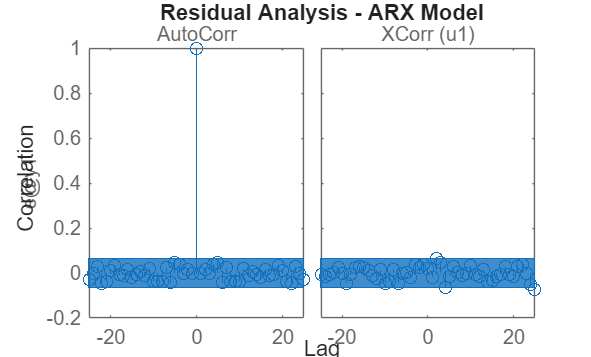


% ARX Residuals
figure();
resid(x_test, sys_arx);
title('Residual Analysis - ARX Model');
xlabel('Lag');
ylabel('Correlation');

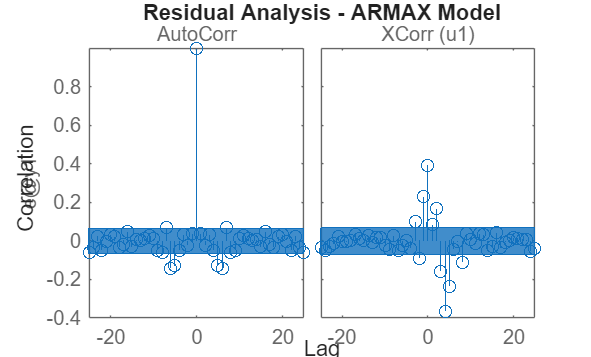


% ARMAX Residuals
figure();
resid(x_test, sys_armax);
title('Residual Analysis - ARMAX Model');
xlabel('Lag');
ylabel('Correlation');

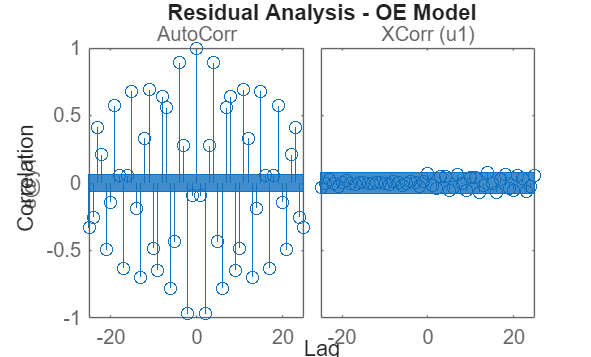


% OE Residuals
figure();
resid(x_test, sys_oe);
title('Residual Analysis - OE Model');
xlabel('Lag');
ylabel('Correlation'); % highly auto corr

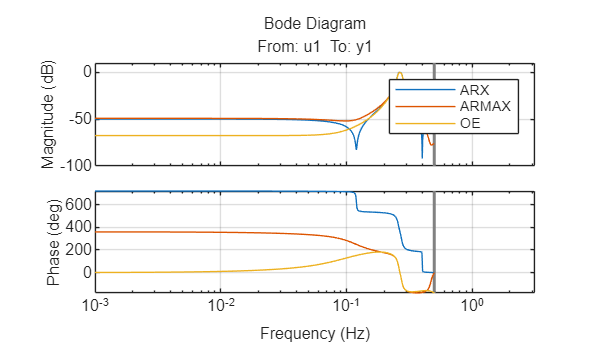


opts = bodeoptions;
opts.FreqUnits = 'Hz';

figure();
bode(sys_arx, sys_armax, sys_oe, opts);
legend('ARX', 'ARMAX', 'OE');
grid on;

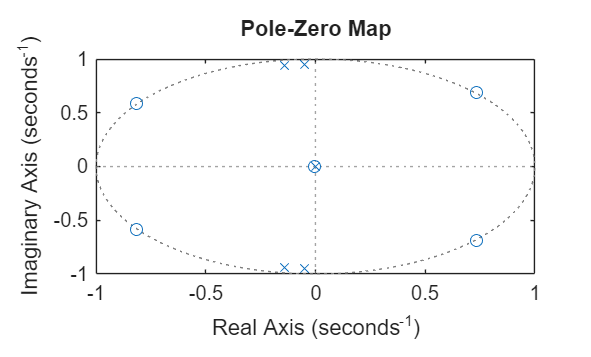



figure;
pzmap(sys_arx);

Compare the FRF with the parametric model

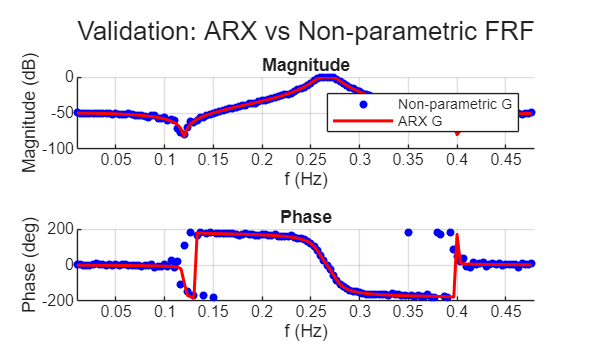

% make G arx for comparison
G_arx = squeeze(freqresp(sys_arx, w_bins));

% Plot magnitude comparison
figure; tcl = tiledlayout(2,1);
title(tcl, 'Validation: ARX vs Non‑parametric FRF');

% Magnitude
nexttile; hold on; grid on;
xlabel('f (Hz)'); ylabel('Magnitude (dB)'); title('Magnitude');
plot(bins*f0, db(abs(G(bins+1))), 'b.', 'MarkerSize', 12, 'DisplayName', 'Non‑parametric G');
plot(bins*f0, db(abs(G_arx)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'ARX G');
legend(); xlim([fmin fmax]);

% Phase
nexttile; hold on; grid on;
xlabel('f (Hz)'); ylabel('Phase (deg)'); title('Phase');
plot(bins*f0, angle(G(bins+1))*180/pi, 'b.', 'MarkerSize', 12);
plot(bins*f0, angle(G_arx)*180/pi, 'r-', 'LineWidth', 1.5);
xlim([fmin fmax]);

## Part 4: Experimental verification of variance estimates

4.1 (4 points) We would like to get an understanding of the mechanism behind the estimation of the variance of identified parameters. To this end, we are going to introduce experiment repetition as a way to estimate the variance of an estimated model. We do this by performing Monte Carlo simulations, that is, repeating Question 3 for 100 times. Inspect the parameters obtained from the Monte Carlo simulations. Do we always get similar results from the different simulation runs? If not, could you explain why?

% clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2;
Ts = 1/fs;  % sampling interval in seconds
runs = 100 % monte carlo iterations

runs = 100


na = 4; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 4; % nc is the order of the polynomial C(q)
nk = 0; % nk is the input-output delay

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.01 0.45] / (fn);
[b_filt, a_filt] = butter(4, wn, 'bandpass');
r_filtered = filtfilt(b_filt, a_filt, r_white_noise);

% make the r signal and scale to stay within saturation limits
safe_amplitude = 2.2;             
r_scaled = r_filtered / max(abs(r_filtered));   
r = safe_amplitude * r_scaled;

mode = 'open loop';

opt = arxOptions;
opt.Focus = 'simulation';
opt.EnforceStability = true;

sys_all = cell(1, runs);

% Do x amounts of runs (Monte Carlo)
for i = 1:runs
    [u, y] = assignment_sys_14(r, mode);
    data = iddata(y, u, Ts);

    sys_mc = arx(data, [na, nb, nk], opt);
    sys_all{i} = sys_mc;  
    
    A_params(i, :) = sys_mc.A(2:end); % remove the 1 (lecture 5/6)
    B_params(i, :) = sys_mc.B((end - nb + 1):end); % grab last 6 parameters ignore delay 0 

    if mod(i, 10) == 0
        disp("Iteration: " + i + "/ 100")
    end
end

Iteration: 10/ 100
Iteration: 20/ 100
Iteration: 30/ 100
Iteration: 40/ 100
Iteration: 50/ 100
Iteration: 60/ 100
Iteration: 70/ 100
Iteration: 80/ 100
Iteration: 90/ 100
Iteration: 100/ 100



% getcov of the last signal
cov_matrix = getcov(sys_mc);
% split in var A and B
var_A = diag(cov_matrix(1:na,1:na))';
var_B = diag(cov_matrix(na+1:na+nb,na+1:na+nb))';

% get simulation var
sim_var_A = var(A_params, 0, 1);
sim_var_B = var(B_params, 0, 1);

% compare simulation var with single run var
error_A_abs = abs(sim_var_A - var_A);
error_A_rel = (error_A_abs ./ var_A) * 100;

error_B_abs = abs(sim_var_B - var_B);
error_B_rel = (error_B_abs ./ var_B) * 100;

disp('--- Variance Comparison A(q) ---');

--- Variance Comparison A(q) ---


disp('Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)');

Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)


for i = 1:na
    fprintf('a_%d       | %1.4e      | %1.4e       | %2.2f%%\n', i, var_A(i), sim_var_A(i), error_A_rel(i));
end

a_1       | 8.9043e-06      | 9.5362e-06       | 7.10%
a_2       | 7.6947e-06      | 7.7927e-06       | 1.27%
a_3       | 9.6366e-06      | 9.7571e-06       | 1.25%
a_4       | 6.6361e-06      | 6.9127e-06       | 4.17%



disp('--- Variance Comparison B(q) ---');

--- Variance Comparison B(q) ---


disp('Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)');

Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)


for i = 1:nb
    fprintf('b_%d       | %1.4e      | %1.4e       | %2.2f%%\n', i, var_B(i), sim_var_B(i), error_B_rel(i));
end

b_1       | 6.0480e-09      | 5.4005e-09       | 10.71%
b_2       | 7.2620e-09      | 9.8938e-09       | 36.24%
b_3       | 6.8632e-09      | 7.4072e-09       | 7.93%
b_4       | 7.3531e-09      | 6.8383e-09       | 7.00%
b_5       | 7.7328e-09      | 6.5796e-09       | 14.91%
b_6       | 8.7576e-09      | 1.1053e-08       | 26.21%




% make bode plot with std
w = logspace(-3, log10(0.5), 300)';

mag_all = zeros(length(w), runs);
phase_all = zeros(length(w), runs);

% get all magnitudes and phase of all monte carlo runs
for i = 1:runs
    [mag, phase, ~] = bode(sys_all{i}, 2*pi*w);
    mag_all(:, i) = 20*log10(squeeze(mag));
    phase_all(:, i) = squeeze(phase);
    
    if mod(i, 10) == 0
        disp("Bode: " + i + "/100")
    end
end

Bode: 10/100
Bode: 20/100
Bode: 30/100
Bode: 40/100
Bode: 50/100
Bode: 60/100
Bode: 70/100
Bode: 80/100
Bode: 90/100
Bode: 100/100


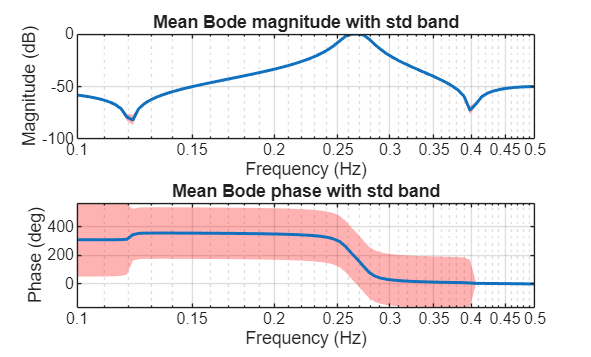


mag_mean = mean(mag_all, 2);
mag_std = std(mag_all, 0, 2);
phase_mean = mean(phase_all, 2);
phase_std = std(phase_all, 0, 2);

figure;

subplot(2,1,1)
upper = mag_mean + mag_std;
lower = mag_mean - mag_std;
fill([w; flipud(w)], [upper; flipud(lower)], 'r', ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
plot(w, mag_mean, 'LineWidth', 1.5);
set(gca, 'XScale', 'log', 'XLim', [1e-1 0.5]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Mean Bode magnitude with std band');

subplot(2,1,2)
upper = phase_mean + phase_std;
lower = phase_mean - phase_std;
fill([w; flipud(w)], [upper; flipud(lower)], 'r', ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
plot(w, phase_mean, 'LineWidth', 1.5);
set(gca, 'XScale', 'log', 'XLim', [1e-1 0.5]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
title('Mean Bode phase with std band');

## Part 5 MIMO

First FRF identification with schroeder 

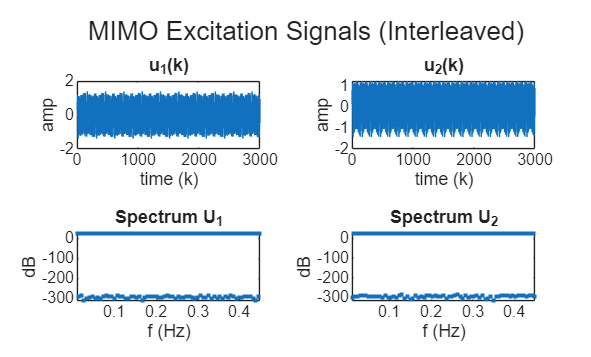

%% Part 2: Nonparametric Identification via Schroeder Multisine (now for MIMO)
% Setup parameters
N = 300;            % Samples per period
fs = 1.0;           % Sampling frequency (Hz)
Ts = 1/fs;
f0 = fs/N;          % Frequency resolution
N_per = 10;          % Number of periods

% Frequency Grid Design
fmin = 0.01; 
fmax = 0.45;        
nmin = ceil(fmin/f0);
nmax = floor(fmax/f0);
bins = nmin:nmax;   % Linear grid for Schroeder efficiency
F = length(bins);   % Number of excited frequencies

% For mimo give even bins to u1 and odd bins to u2 to keep them decoupled
bins_u1 = bins(1:2:end); % Odd bins
bins_u2 = bins(2:2:end); % Even bins

%% Setup Butterworth Filter F(q)
btt_num = [0.7157 1.4315 0.7157];
btt_den = [1 1.3490 0.5140];
Ts = 1.0; 
F_butter = tf(btt_num, btt_den, Ts);

% schroeder phase
% Formula: phi_k = -k*(k-1)*pi/F
k_idx = 0:F-1; 
phi_schroeder = -k_idx .* (k_idx + 1) * pi / F;

%% Rescale Amplitudes (Inverse Filter Gain)
% We counteract the Butterworth filter F(q) to keep excitation flat at the plant
w_bins = 2 * pi * (bins * f0); 
[mag, ~] = freqresp(F_butter, w_bins);
gain_array = max(squeeze(mag), 1e-4); % Avoid division by zero
A = 1 ./ gain_array; 

%% Construct Frequency Domain Signal
u1 = zeros(N, 1);
u2 = zeros(N, 1);

% Generate phases and spectra for u1
F1 = length(bins_u1);
k1 = 0:F1-1;
phi1 = -k1 .* (k1 + 1) * pi / F1;
A1 = A(1:2:end);
u1(bins_u1 + 1) = A1 .* exp(1j * phi1');

% Generate phases and spectra for u2
F2 = length(bins_u2);
k2 = 0:F2-1;
phi2 = -k2 .* (k2 + 1) * pi / F2;
A2 = A(2:2:end);
u2(bins_u2 + 1) = A2 .* exp(1j * phi2');

% Perform IFFT and ensure real signal
u1_p = real(ifft(u1)) * N;
u2_p = real(ifft(u2)) * N;

% Scale to maximize SNR without hitting the 2.2V saturation limit
total_max = max([abs(u1_p); abs(u2_p)]);
u1_scaled = 2.0 * (u1_p / total_max);
u2_scaled = 2.0 * (u2_p / total_max);

r_mimo = [repmat(u1_scaled, N_per, 1), repmat(u2_scaled, N_per, 1)];

mode = 'MIMO';
[u, y] = assignment_sys_14(r_mimo, mode);

% Discard the first period (transients) and average the rest
P_skip = 1;
u_matrix = reshape(u, N, N_per, 2);
y_matrix = reshape(y, N, N_per, 2);

u_avg = squeeze(mean(u_matrix(:, P_skip+1:end, :), 2));
y_avg = squeeze(mean(y_matrix(:, P_skip+1:end, :), 2));

U_fft = fft(u_avg);
Y_fft = fft(y_avg);

% Frequency Response Function (FRF)
G11 = Y_fft(bins_u1 + 1, 1) ./ U_fft(bins_u1 + 1, 1);
G21 = Y_fft(bins_u1 + 1, 2) ./ U_fft(bins_u1 + 1, 1);
G12 = Y_fft(bins_u2 + 1, 1) ./ U_fft(bins_u2 + 1, 2);
G22 = Y_fft(bins_u2 + 1, 2) ./ U_fft(bins_u2 + 1, 2);

f_vec = (0:N-1)*f0;
idx_plot = bins + 1; % Only plot where we actually excited the system

% Input response
figure; tcl1 = tiledlayout(2,2); title(tcl1, 'MIMO Excitation Signals (Interleaved)');
% Time domain
nexttile; plot(u(:,1)); xlabel('time (k)'); ylabel('amp'); title('u_1(k)');
nexttile; plot(u(:,2)); xlabel('time (k)'); ylabel('amp'); title('u_2(k)');
% Frequency domain (Averaged Spectra)
nexttile; plot(f_vec(1:end/2), db(abs(U_fft(1:end/2, 1))), '.'); 
xlabel('f (Hz)'); ylabel('dB'); title('Spectrum U_1'); xlim([fmin fmax]);
nexttile; plot(f_vec(1:end/2), db(abs(U_fft(1:end/2, 2))), '.'); 
xlabel('f (Hz)'); ylabel('dB'); title('Spectrum U_2'); xlim([fmin fmax]);

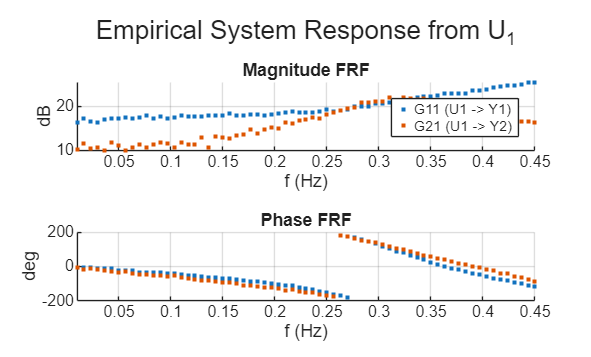


% u1 to Y
figure; tcl2 = tiledlayout(2,1); title(tcl2, 'Empirical System Response from U_1');
% Magnitude
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude FRF');
plot(bins_u1*f0, db(abs(G11)), '.', 'DisplayName', 'G11 (U1 -> Y1)');
plot(bins_u1*f0, db(abs(G21)), '.', 'DisplayName', 'G21 (U1 -> Y2)');
legend; xlim([fmin fmax]);
% Phase
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase FRF');
plot(bins_u1*f0, angle(G11)*180/pi, '.');
plot(bins_u1*f0, angle(G21)*180/pi, '.');
xlim([fmin fmax]);

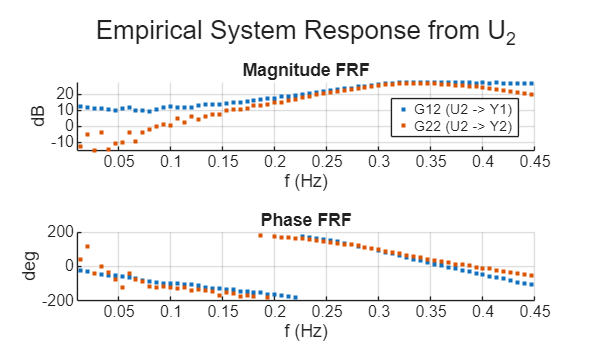


% u2 to Y
figure; tcl3 = tiledlayout(2,1); title(tcl3, 'Empirical System Response from U_2');
% Magnitude
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude FRF');
plot(bins_u2*f0, db(abs(G12)), '.', 'DisplayName', 'G12 (U2 -> Y1)');
plot(bins_u2*f0, db(abs(G22)), '.', 'DisplayName', 'G22 (U2 -> Y2)');
legend; xlim([fmin fmax]);
% Phase
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase FRF');
plot(bins_u2*f0, angle(G12)*180/pi, '.');
plot(bins_u2*f0, angle(G22)*180/pi, '.');
xlim([fmin fmax]);

### Maybe add the noise model also here!!!!!!

### Parametric Modeling

N_mimo = 3000;
fs = 1.0;
Ts = 1/fs;

% Independent sequences so the inputs are uncorrelated (gaussian noise)
r1 = randn(N_mimo, 1);
r2 = randn(N_mimo, 1);

% Bandpass filter to stay within excitation limits 
wn = [0.01 0.45] / (fs/2);
[b_filt, a_filt] = butter(4, wn, 'bandpass');
r1_f = filtfilt(b_filt, a_filt, r1);
r2_f = filtfilt(b_filt, a_filt, r2);

% make the r signal and scale to stay within saturation limits
safe_amplitude = 2.2; 
r1_scaled = r1_f / max(abs(r1_f));  
r2_scaled = r2_f / max(abs(r2_f));  

r_mimo = safe_amplitude * [r1_scaled, r2_scaled];  

max(abs(r_mimo))

ans =     2.2000    2.2000



mode = 'MIMO';
[u_mimo, y_mimo] = assignment_sys_14(r_mimo, mode);
data_mimo = iddata(y_mimo, u_mimo, Ts);

% MIMO ARMAX Estimation
% na: Shared denominator order
% nb: 2x2 matrix for 2 inputs and 2 outputs
% nc: Noise model order
% nk: 2x2 matrix for input-output delays
na = [6 6; 
      6 6];
nb = [6 6;  % Numerator orders for [G11 G12]
      6 6]; % Numerator orders for [G21 G22]
nc = [4;
        4];
nk = [0 0;  % Delays for [G11 G12]
      0 0]; % Delays for [G21 G22]

opt = arxOptions;
opt.Focus = 'simulation';
opt.EnforceStability = true;

sys_mimo_arx = arx(data_mimo, [na nb nk], opt);

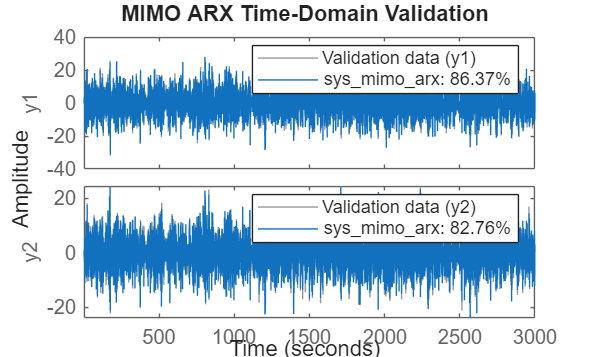


figure;
compare(data_mimo, sys_mimo_arx);
title('MIMO ARX Time-Domain Validation');

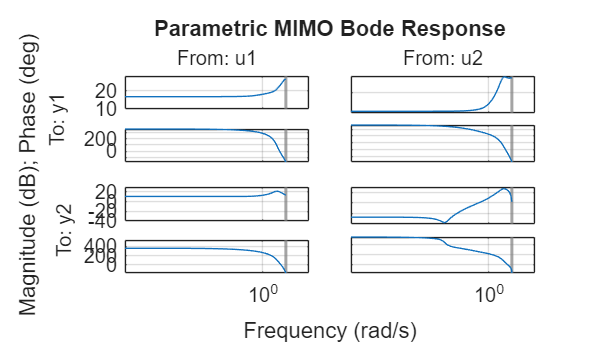


figure;
bode(sys_mimo_arx);
grid on;
title('Parametric MIMO Bode Response');

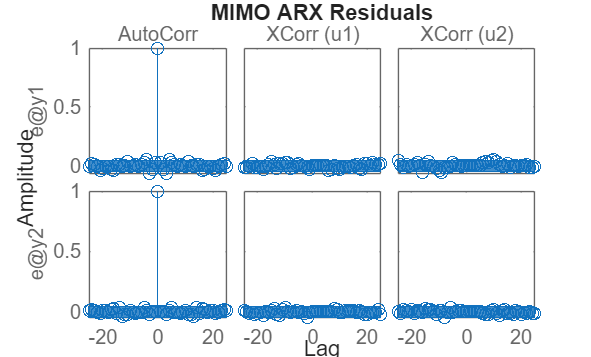


figure;
resid(data_mimo, sys_mimo_arx);
title('MIMO ARX Residuals');

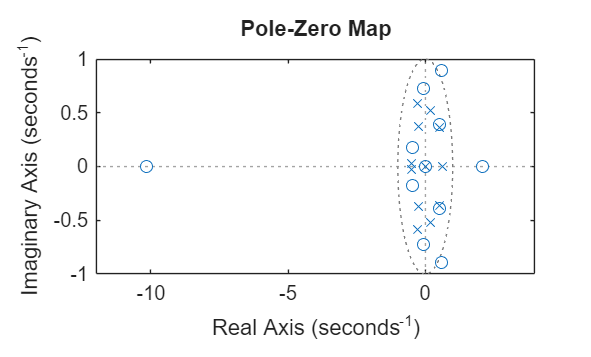


figure;
pzmap(sys_mimo_arx);

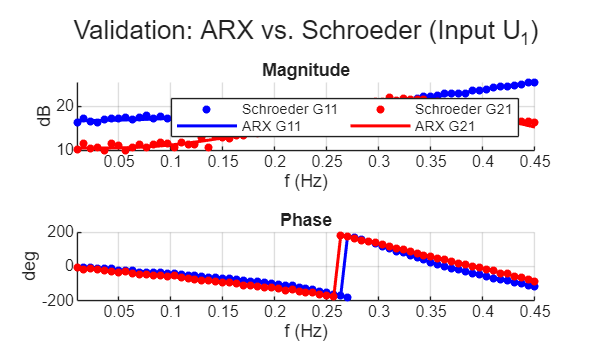



% Compare FRF with ARMAX
w_bins_u1 = 2 * pi * bins_u1 * f0; 
w_bins_u2 = 2 * pi * bins_u2 * f0;

G_arx_G11 = squeeze(freqresp(sys_mimo_arx(1,1), w_bins_u1)); 
G_arx_G21 = squeeze(freqresp(sys_mimo_arx(2,1), w_bins_u1)); 
G_arx_G12 = squeeze(freqresp(sys_mimo_arx(1,2), w_bins_u2)); 
G_arx_G22 = squeeze(freqresp(sys_mimo_arx(2,2), w_bins_u2)); 

figure; tcl_u1 = tiledlayout(2,1); title(tcl_u1, 'Validation: ARX vs. Schroeder (Input U_1)');

% Magnitude U1
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude');
plot(bins_u1*f0, db(abs(G11)), 'b.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G11');
plot(bins_u1*f0, db(abs(G_arx_G11)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'ARX G11');
plot(bins_u1*f0, db(abs(G21)), 'r.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G21');
plot(bins_u1*f0, db(abs(G_arx_G21)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'ARX G21');
legend('NumColumns', 2); xlim([fmin fmax]);

% Phase U1
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase');
plot(bins_u1*f0, angle(G11)*180/pi, 'b.', 'MarkerSize', 12);
plot(bins_u1*f0, angle(G_arx_G11)*180/pi, 'b-', 'LineWidth', 1.5);
plot(bins_u1*f0, angle(G21)*180/pi, 'r.', 'MarkerSize', 12);
plot(bins_u1*f0, angle(G_arx_G21)*180/pi, 'r-', 'LineWidth', 1.5);
xlim([fmin fmax]);

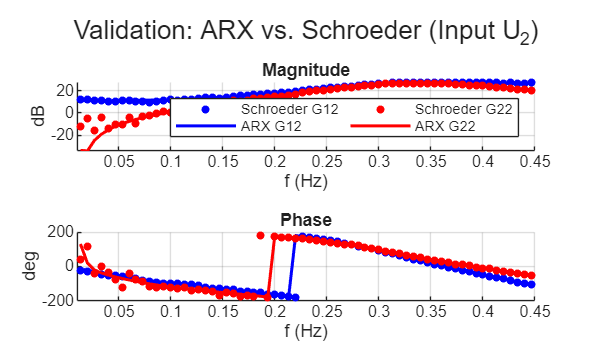


%%%%%

figure; tcl_u2 = tiledlayout(2,1); title(tcl_u2, 'Validation: ARX vs. Schroeder (Input U_2)');

% Magnitude U2
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude');
plot(bins_u2*f0, db(abs(G12)), 'b.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G12');
plot(bins_u2*f0, db(abs(G_arx_G12)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'ARX G12');
plot(bins_u2*f0, db(abs(G22)), 'r.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G22');
plot(bins_u2*f0, db(abs(G_arx_G22)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'ARX G22');
legend('NumColumns', 2); xlim([fmin fmax]);

% Phase U2
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase');
plot(bins_u2*f0, angle(G12)*180/pi, 'b.', 'MarkerSize', 12);
plot(bins_u2*f0, angle(G_arx_G12)*180/pi, 'b-', 'LineWidth', 1.5);
plot(bins_u2*f0, angle(G22)*180/pi, 'r.', 'MarkerSize', 12);
plot(bins_u2*f0, angle(G_arx_G22)*180/pi, 'r-', 'LineWidth', 1.5);
xlim([fmin fmax]);